clear;
close all;
% create circle
x= linspace(-128,128,512); % x-size of image
z= linspace(-128,128,512); % y-size of image
[x,z] = meshgrid(x,z);
J = zeros(size(x)); % allocate space for circle and initiate image
J((x.^2+z.^2)<=(10)^2)=1; % create circle in image
N = [5, 25, 50, 75]; % number of projections
SNR_I = zeros(1, length(N)); % allocate space for SNR values
for j = 1:length(N)
    I = zeros(512, 512, N(j)); % allocate space for all images collected
    I(:,:,1) = J;
    % create gif
    filename = ['motionblur',num2str(N),'.gif'];
    figure
    imagesc(I(:,:,1))
    colormap('gray')
    axis('square')
    title(['original image, N=', num2str(N)])
    F = getframe(gcf);
    imwrite(rgb2gray(F.cdata), filename, 'gif', 'DelayTime', 0, 'LoopCount', inf);
    clf
    % initialize projection angles
    first_angle = 0;
    last_angle = 180;
    theta_radon = first_angle:last_angle; % radon transform from 0:180 degrees
    theta_motion = 0; % starting angle for motion blur
    count = 1; 
    angles = theta_radon(count:floor(count+(180/N(j))-1)); % get the first set of angles imaged during radon transform
    rad_I = radon(I(:,:,1), angles); % compute radon transform for defined angles on stationary image
    inv_I = iradon(rad_I, angles); % compute inverse radon transform for defined angles  on stationary image
    count = count + floor(180/N(j));
    for i = 2:N(j)
        theta_motion = floor(360*rand(1,1)); % randomize angle of blur
        blur = 90*rand(1,1)+10; % randomize intensity of blur
        H = fspecial('motion', blur, theta_motion); % create motion blur
        I(:,:,i) = conv2(I(:,:,1), H, "same"); % convolve motion blur with image
        % create gif
        figure
        imagesc(I(:,:,i))
        colormap('gray')
        axis('square')
        title(['original image, N=', num2str(N)])
        F = getframe(gcf);
        imwrite(rgb2gray(F.cdata), filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0);
        clf
        % initialize next set of projection angles
        angles = theta_radon(count:floor(count+(180/N(j))-1)); % extract subsequent angles for radon transform
        rad_I = radon(I(:,:,i), angles); % compute radon transform for defined angles on specified image  
        inv_I = inv_I + iradon(rad_I, angles); % compute inverse radon transform for defined angles on specified image 
        count = count + floor(180/N(j));
    end
    % SNR Calculations
    point1 = inv_I(257,200:300); % select region with target object
    noise_bg_I = inv_I(:,300:end); % select region corresponding to background 
    std_bg_I = std2(noise_bg_I); % standard deviation of background 
    mean_bg_I = mean2(noise_bg_I); % mean of background
    SNR_I(j) = (max(point1)-mean_bg_I)/std_bg_I
end

SNR_I =   101.8648         0         0         0


SNR_I =   101.8648   51.3084         0         0


SNR_I =   101.8648   51.3084   41.4469         0


SNR_I =   101.8648   51.3084   41.4469   38.9143


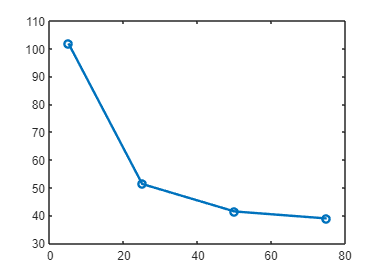

plot(N, SNR_I, '-o', 'LineWidth', 2)

xlabel('N Projections')
ylabel('SNR')
title('SNR vs. Number of Projections')